## Random Walker

rng(0); %setting the seed
z = rand(1000,10000);
z(z > 0.5)=1;
z(z <= 0.5)=-1;

Numbers generated will be equally distributed from 0 to 1. Here if the number is greater than 0.5 we will assume walker goes in positive direction else in negative direction.

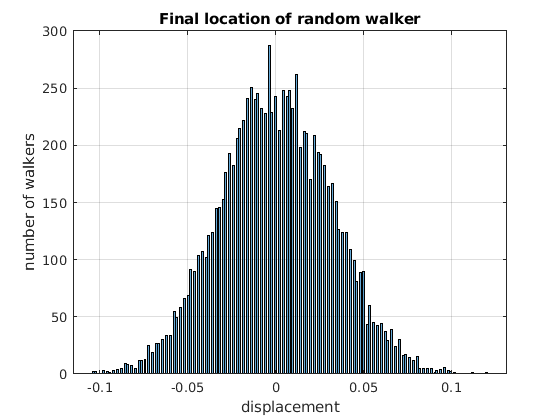

p = sum(z)./1000;
histogram(p,200);
xlabel('displacement');
ylabel('number of walkers');
grid on;
title 'Final location of random walker'


exp = 0;
for i=1:1:10000
    exp = exp + p(1,i);
end

exp = exp./10000;



var = 0;
for i=1:1:10000
    var= var + (p(1,i) - exp).*(p(1,i)-exp);
end
var = var./10000;
disp("expectation value = "  + exp);

expectation value = 0.0001386


disp("variance is = " + var);

variance is = 0.00099093


Value of true mean as a function of no.of steps(n) and lenth of each step(l) = 0

Value of true variance as a function of no.of steps(n) and lenth of each step(l) = $nl^{2}$

True expectation = 0;

True variance = $1000*10^{-6} = 10^{-3}$

Error in empirically determined mean = 0.0001386

Error in empirically determined variance = $10^{-3}$ - 0.00099093 = 0.00000907